# merged

# Linear and circular convolution

%Linear
x=[5 7 3 9 1 0];
h=[1 3 5 7];
l1 = length(x);
l2 = length(h);
N = l1+l2-1;

x = [x, zeros(1,N)];
h = [h, zeros(1,N)];
y = zeros(1,N);

for n = 1:N
    for k =  1:n
        y(n) = y(n) + x(k)*h(n-k+1);
    end
end

n = 0:N-1;
disp(y)

     5    22    49    88    92    69    68     7     0



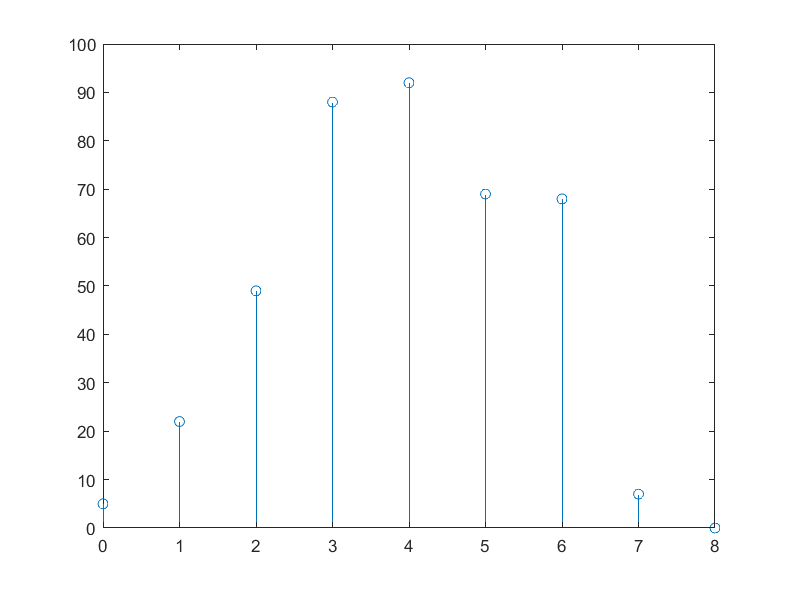

stem(n,y)


%Circular
clear all;
clc;
x=[2 1 2 1];
h=[1 2 3 4];
l1 = length(x);
l2 = length(h);
N = max(l1,l2);

x = [x, zeros(1,N-l1)];
h = [h, zeros(1,N-l2)];
y = zeros(1,N);

for n = 1:N
    for m =  1:N
        j = mod(n-m,N);
        j = j+1;
        y(n) = y(n) + x(m)*h(j);
    end
end
disp(y)

    14    16    14    16



cconv(x,h,N)

ans =     14    16    14    16


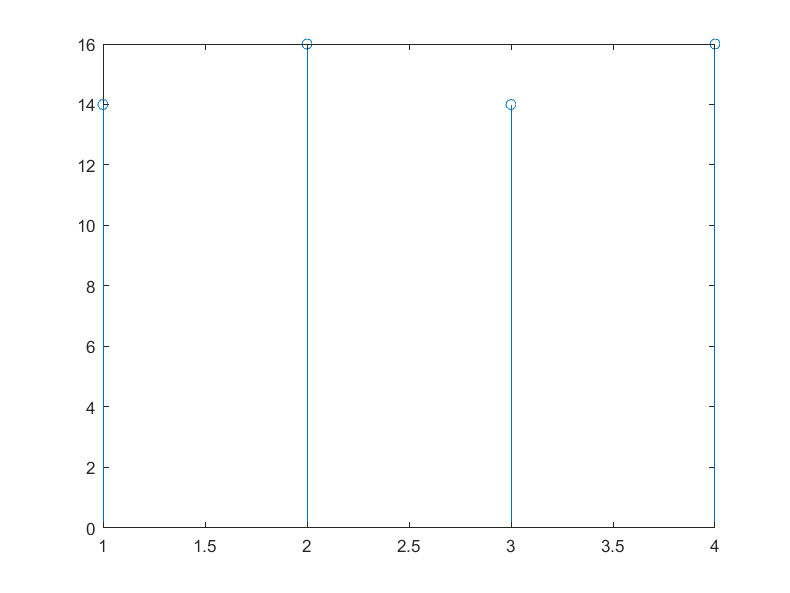

stem(y)

# Sampling practice

clc;
clear all;

%Input signal
t = -10:0.01:10;
T=4;
fm = 1/T;
sig = cos(2*pi*fm*t);
subplot(2,2,1);
plot(t,sig);
title('Input signal')
xlabel('Time')
ylabel('amplitude')

%Let us sample

fs1 = 1.6*fm;
fs2 = 2*fm;
fs3 = 4*fm;

%Undersampling
n1 = -4:1:4;
s1 = cos(2*pi*n1*fm/fs1);
subplot(2,2,2);
plot(n1,s1);
title('Undersampling')
xlabel('Time')
ylabel('amplitude')

%Normal / Nyquist
n2 = -5:1:5;
s2 = cos(2*pi*n2*fm/fs2);
subplot(2,2,3);
stem(n2,s2);
hold on;
subplot(2,2,3);
plot(n2,s2);
title('Normal sampling')
xlabel('Time')
ylabel('amplitude')

%Oversampling
n3 = -10:1:10;
s3 = cos(2*pi*n3*fm/fs3);
subplot(2,2,4);
stem(n3,s3);
hold on;
subplot(2,2,4);
plot(n3,s3);
title('Oversampling')
xlabel('Time')
ylabel('amplitude')

# Waveform practice

%Unit impulse
n = [-10:1:10];
x = [zeros(1,10), ones(1,1), zeros(1,10)];
subplot(3,2,1)
stem(n,x)
title('Unit impulse')
xlabel('n')
ylabel('x')

%Unit step
n = [-10:1:10];
x = [zeros(1,10), ones(1,1), ones(1,10)];
subplot(3,2,2)
stem(n,x)
title('Unit step')
xlabel('n')
ylabel('x')

%Unit ramp
n = [-10:1:10];
x = n;
subplot(3,2,3)
stem(n,x)
title('Unit ramp')
xlabel('n')
ylabel('x')

%Exponential increase
a = 2;
n = 0:0.5:5;
x = exp(a*n);
subplot(3,2,4)
stem(n,x)
title('Exp increase')
xlabel('n')
ylabel('x')

%Exponential decrease
a = 2;
n = 0:0.5:5;
x = exp(-a*n);
subplot(3,2,5)
stem(n,x)
title('Exp decrease')
xlabel('n')
ylabel('x')

%Square
f = 0.6;
n = 0:0.5:5;
x = square(2*pi*f*n);
subplot(3,2,6)
stem(n,x)
title('Square')
xlabel('n')
ylabel('x')

%Sawtooth
f = 0.6;
n = 0:0.5:5;
x = sawtooth(2*pi*f*n);
figure
stem(n,x)
title('Sawtooth')
xlabel('n')
ylabel('x')

%sine
f = 0.6;
n = 0:0.5:5;
x = sin(2*pi*f*n);
figure
stem(n,x)
title('sin')
xlabel('n')
ylabel('x')

%cosine
f = 0.6;
n = 0:0.5:5;
x = cos(2*pi*f*n);
figure
stem(n,x)
title('cos')
xlabel('n')
ylabel('x')

# DFT and IDFT

clc;
clear all;

%DFT
xn = [1 0 2 3 1 5 3 0];
ln = length(xn);
i = sqrt(-1);
xk = zeros(1,ln);
ixk = zeros(1,ln);

for k = 0:ln-1
    for n = 0:ln-1
        
        xk(k+1) = xk(k+1) + (xn(n+1)*exp((-i)*2*pi*k*n/ln));
        
    end
end

disp(xk);
xn;
mag = abs(xk);
phase = angle(xk);

t=0:ln-1;
subplot(3,2,1)
stem(t,xn)
title('input signal')
xlabel('time')
ylabel('amplitude')

subplot(3,2,2)
stem(t,mag)
title('DFT mag')
xlabel('time')
ylabel('magnitude')

subplot(3,2,3)
stem(t,phase)
title('DFT phase')
xlabel('time')
ylabel('phase')

subplot(3,2,4)
stem(t,xk)
title('DFT')
xlabel('time')
ylabel('xk')

%IDFT
for n = 0:ln-1
    for k = 0:ln-1
        
        ixk(n+1) = ixk(n+1) + (xk(k+1)*exp((i)*2*pi*k*n/ln));
        
    end
end
ixk = ixk./ln;
ixk=abs(ixk);
subplot(3,2,5)
stem(t,ixk)
title('iDFT')
xlabel('time')
ylabel('ixk')


# DCT and DWT

%DCT
clc
close all
im=imread('penguins.jpg');
im=double(im)/255;
im=rgb2gray(im);
subplot(211)
imshow(im)
title('Original image');
img_dct=dct2(im);
img_pow=(img_dct).^2

img_pow = 	1.0e+03 *

    9.4130    0.0000    0.0038    0.0003    0.0005    0.0004    0.0015    0.0001    0.0008    0.0009    0.0001    0.0005    0.0009    0.0000    0.0015    0.0003    0.0003    0.0003    0.0001    0.0001    0.0001    0.0012    0.0003    0.0004    0.0007    0.0001    0.0000    0.0000    0.0006    0.0002    0.0002    0.0003    0.0000    0.0000    0.0000    0.0002    0.0002    0.0000    0.0001    0.0000    0.0000    0.0000    0.0002    0.0000    0.0002    0.0002    0.0000    0.0000    0.0000    0.0002
    0.3956    0.0000    0.0000    0.0001    0.0000    0.0001    0.0008    0.0000    0.0002    0.0002    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0002    0.0001    0.0003    0.0004    0.0000    0.0002    0.0002    0.0001    0.0000    0.0004    0.0002    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0

img_pow=img_pow(:);
[B,index]=sort(img_pow);
B=flipud(B);
index=flipud(index);
compressed_dct=zeros(size(im));
coeff=2000;
for k=1:coeff
    compressed_dct(index(k))=img_dct(index(k));
end
im_dct=idct2(compressed_dct);
subplot(212)
imshow(im_dct)
title('DCT Compress Image');

imwrite(im_dct,'compress.jpg')
%DWT
clear all;
close all;
i=imread('Tulips.jpg')

i = 480×600×3 uint8 array
i(:,:,1) =

    21    50    80   102   123   139   154   169   172   173   172   172   171   171   170   170   176   175   178   182   187   192   198   201   202   204   204   207   208   209   211   211   209   209   209   210   208   206   205   204   199   198   198   197   200   199   188   176   175   175   177   179   184   190   198   203   203   208   216   220   219   219   219   219   219   222   224   226   227   227   228   229   228   228   227   225   219   216   213   211   204   200   192   185   176   165   149   136   110    84    60    37    15     5     6     9     2     3     5     6     8     9     8     7    14    15    16    16    16    17    19    18    23    22    26    30    30    24    21    20    21    20    19    13     6     3    13    26    38    42    46    52    54    53    51    50    44    36    29    23    21    18    14    11     5     5     6     6     4     3     4     9     8     9    10    12    13    13    13    13  

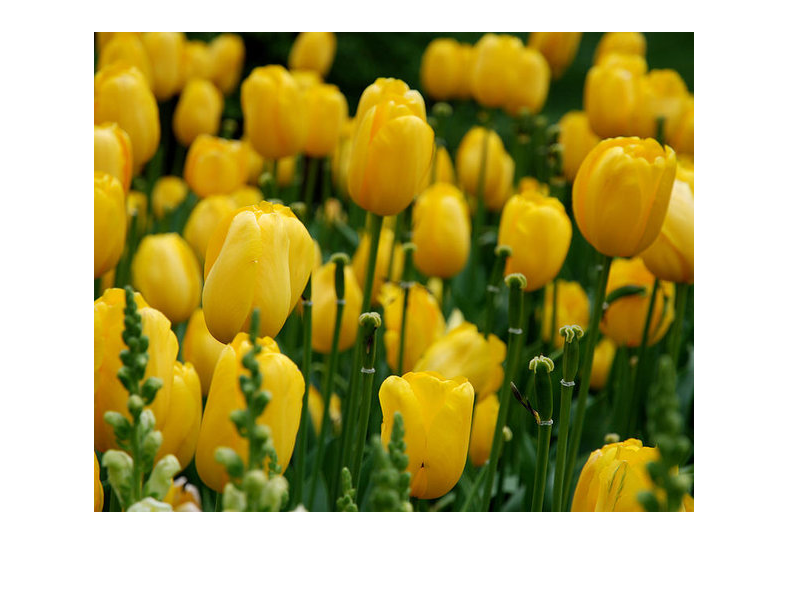

imshow(i)

sX=size(i)

sX =    480   600     3


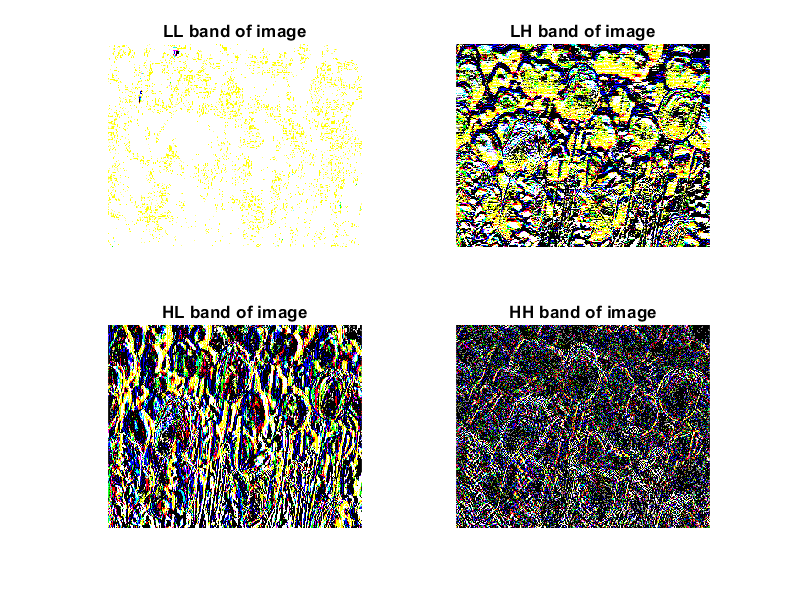

[LL,LH,HL,HH]=dwt2(i,'Haar');
figure(1)
subplot(2,2,1);imshow(LL);title('LL band of image')
subplot(2,2,2);imshow(LH);title('LH band of image')
subplot(2,2,3);imshow(HL);title('HL band of image')
subplot(2,2,4);imshow(HH);title('HH band of image')

X=idwt2(LL,LH,HL,HH,'db1',sX)

X = X(:,:,1) =

   21.0000   50.0000   80.0000  102.0000  123.0000  139.0000  154.0000  169.0000  172.0000  173.0000  172.0000  172.0000  171.0000  171.0000  170.0000  170.0000  176.0000  175.0000  178.0000  182.0000  187.0000  192.0000  198.0000  201.0000  202.0000  204.0000  204.0000  207.0000  208.0000  209.0000  211.0000  211.0000  209.0000  209.0000  209.0000  210.0000  208.0000  206.0000  205.0000  204.0000  199.0000  198.0000  198.0000  197.0000  200.0000  199.0000  188.0000  176.0000  175.0000  175.0000  177.0000  179.0000  184.0000  190.0000  198.0000  203.0000  203.0000  208.0000  216.0000  220.0000  219.0000  219.0000  219.0000  219.0000  219.0000  222.0000  224.0000  226.0000  227.0000  227.0000  228.0000  229.0000  228.0000  228.0000  227.0000  225.0000  219.0000  216.0000  213.0000  211.0000  204.0000  200.0000  192.0000  185.0000  176.0000  165.0000  149.0000  136.0000  110.0000   84.0000   60.0000   37.0000   15.0000    5.0000    6.0000    9.0000    2.0000    3.0000    

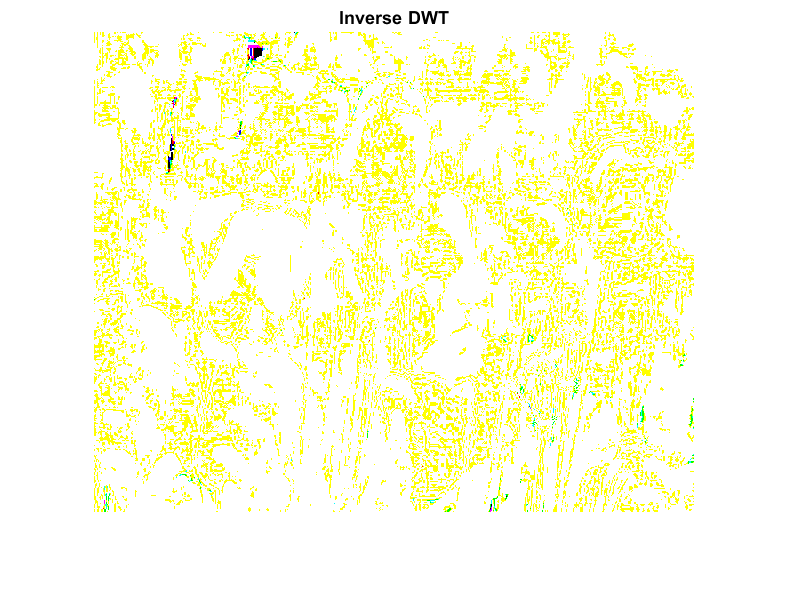

figure(2)
imshow(X)
title('Inverse DWT')